# Principal Component Analysis

**Author: **Scott Campit

## **Summary**

This notebook performs principal component analysis as a linear dimension reduction technique against multiple datasets. The objective of this notebook is to see how much of the variance explained is attributed to each histone marker.

## CCLE Global Chromatin Profiles

First, we'll compute some principal components using the GCPs. The GCPs are already centered to have a mean of 0 and standard deviation of 1. So we can input the proteomics directly.

load ~/Data/Proteomics/CCLE/CCLE_Proteomics.mat
[coeff, score, latent, tsquared, explained, mu] = pca(proteomics);

pca_data =     0.2515   -1.3632   -1.9373   -2.6341   -0.8532   -1.7037   -1.6181    1.0446   -0.7387    0.6792    0.4700    0.6195    0.2867    0.1615   -1.0667   -0.5806    0.2692   -0.0985    0.7668    0.2575    0.0864    0.1776    0.5322    0.2954   -0.0283    0.0198    0.5308   -0.1589   -0.1088    0.4535    0.3922   -0.5430    0.4666   -0.0956   -0.0916    0.1273    0.1299    0.1176   -0.0477   -0.1748   -0.1967   -0.0743
   -3.1839    1.5815   -0.1223    0.2647   -0.1558    0.4330   -0.0987   -0.6795    0.0138    0.3038   -0.8004    0.2455    0.4602    0.2516    0.2208    0.2936    0.1409    1.0056   -0.1757   -0.1690   -0.2704    0.5243   -0.3236   -0.1448    0.0824   -0.2003   -0.2488    0.0421   -0.1654   -0.0437   -0.2168    0.1780    0.2036   -0.0425    0.0296    0.3097    0.0840    0.2508    0.0048   -0.1269   -0.0999   -0.0117
   -0.8418   -0.5135    1.2556   -0.9172   -1.0580    0.0888    0.0829   -0.1489   -0.9658    0.9024    1.0871   -0.0632    0.8265   -0.3944   -0.4

### Get a sense of cell lines that may be outliers

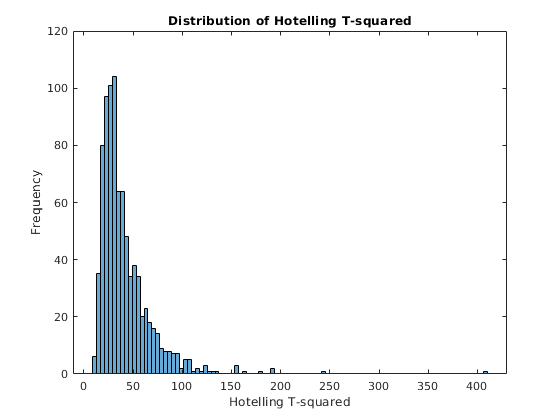

histogram(tsquared, 100)
xlabel('Hotelling T-squared'); ylabel('Frequency');
title('Distribution of Hotelling T-squared')

### Hierarchical clustering for projections of the original data

clustergram(score, 'ColumnLabels', marks, 'Colormap', redbluecmap)

Error using matlab.graphics.primitive.canvas.JavaCanvas/hittest
Invalid or deleted object.

Error in datacursormode>localIsMouseOverDataAnnotatable (line 487)
        hitObj = sv(i).hittest(currentPoint(1),ySv);

Error in datacursormode>localSetUIOn (

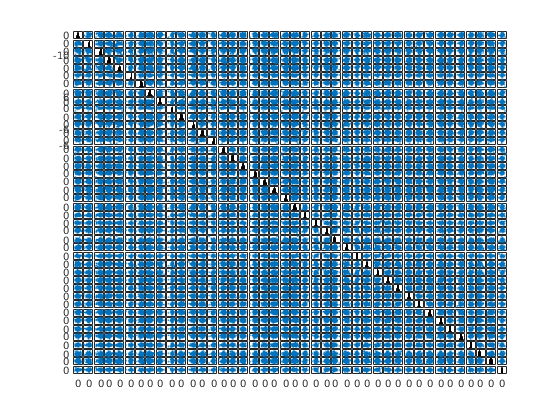

plotmatrix(score)

### SANITY CHECK: Correlation matrix

In short, the scores are uncorrelated because they are projections of the original data.

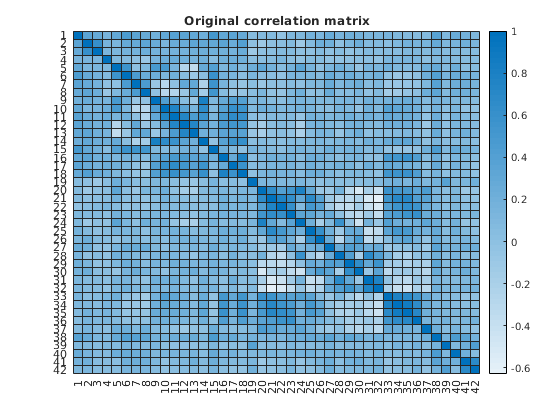

[pcc, pval] = corr(centered_proteomics);
heatmap(pcc)
title('Original correlation matrix');

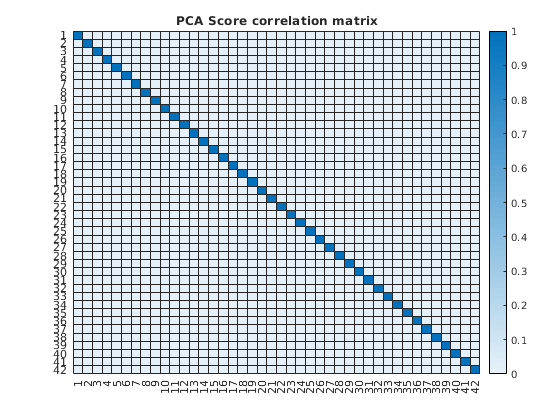

[pcc, pval] = corr(score);
heatmap(pcc);
title('PCA Score correlation matrix');

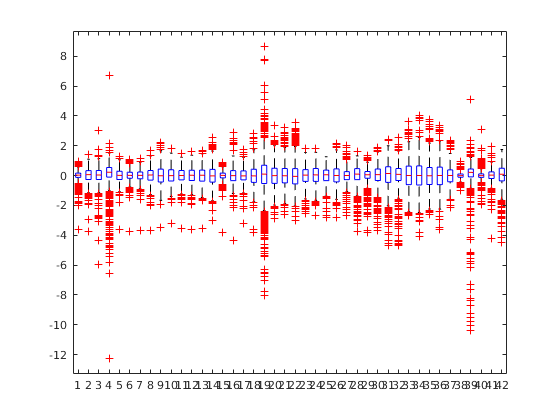

boxplot(centered_proteomics)

centered_proteomics - proteomics

ans =     0.0234    0.0603    0.0383    0.2206    0.0164    0.0129    0.0129    0.0355   -0.0039   -0.0003    0.0071    0.0261    0.0230   -0.0179    0.0131   -0.0062   -0.0176   -0.0199    0.0983   -0.0055   -0.0137   -0.0499    0.0306    0.0553    0.0548    0.0084    0.0037    0.1014    0.0568    0.0654    0.1446    0.0754    0.0129    0.0125   -0.0106    0.0076    0.0072   -0.0014    0.2207   -0.0007    0.0279    0.0832
    0.0234    0.0603    0.0383    0.2206    0.0164    0.0129    0.0129    0.0355   -0.0039   -0.0003    0.0071    0.0261    0.0230   -0.0179    0.0131   -0.0062   -0.0176   -0.0199    0.0983   -0.0055   -0.0137   -0.0499    0.0306    0.0553    0.0548    0.0084    0.0037    0.1014    0.0568    0.0654    0.1446    0.0754    0.0129    0.0125   -0.0106    0.0076    0.0072   -0.0014    0.2207   -0.0007    0.0279    0.0832
    0.0234    0.0603    0.0383    0.2206    0.0164    0.0129    0.0129    0.0355   -0.0039   -0.0003    0.0071    0.0261    0.0230   -0.0179    0.0131  

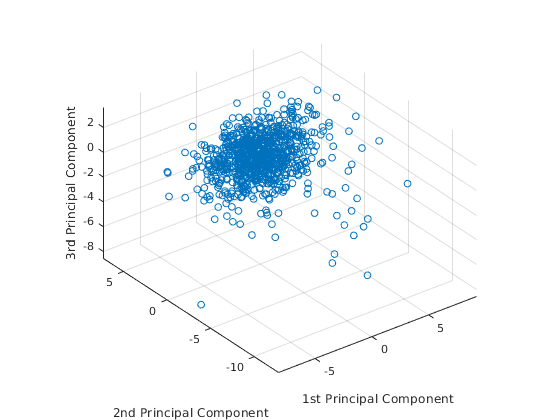

scatter3(score(:,1),score(:,2),score(:,3))
axis equal
xlabel('1st Principal Component')
ylabel('2nd Principal Component')
zlabel('3rd Principal Component')

## Scree plot

First let's compute the total variance from the `explained` variable.

total_var = zeros(length(explained), 1);
for i = 1:length(explained)
    if i == 1
       total_var(i) = explained(i);
    else
       total_var(i) = total_var(i-1) + explained(i);
    end
end

Next, we can reconstruct the scree plot. 95% of the data can be explained by the first 20 scores.

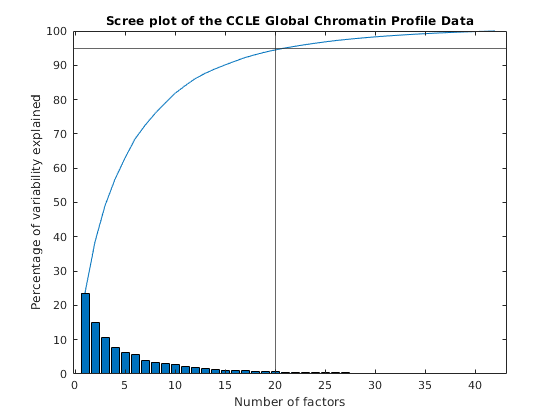

bar(explained);
hold on;
line(1:length(total_var), total_var);
hold off;
yline(95); xline(20);
xlabel('Number of factors'); ylabel('Percentage of variability explained');
title('Scree plot of the CCLE Global Chromatin Profile Data');

scree(latent)

Unrecognized function or variable 'scree'.